## Лабораторна Робота 3

## 1. Завантажити з бібліотеки MATLAB тестове зображення.

image = imread('moon.tif');

## 2. Відобразити вихідні зображення на екрані ПК.

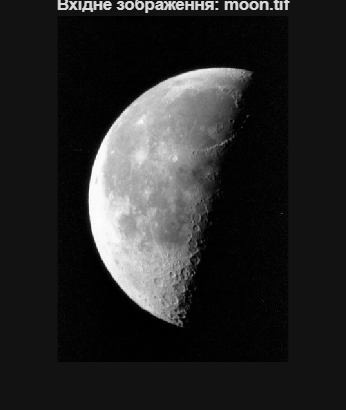

figure, imshow(image), title('Вхідне зображення: moon.tif');

## 3. Здійснити процедуру перекручення зображення змінюючи параметри LEN і THETA.

LEN = 24;
THETA = 10;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(image, PSF, 'conv', 'circular');

## 4. Відобразити перекручене зображення.

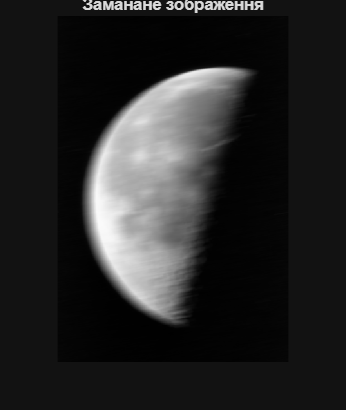

figure, imshow(blurred), title('Замазане зображення');

## 5. Виконати процедуру відновлення зображення.

recovered = deconvwnr(blurred, PSF, 0);

## 6. Відобразити зображення після відновлення.

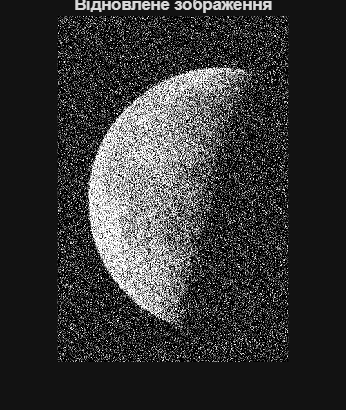

imshow(recovered),title('Відновлене зображення');

## 7. Виконати зашумлення початкового зображення та повторити пункти 2-6.

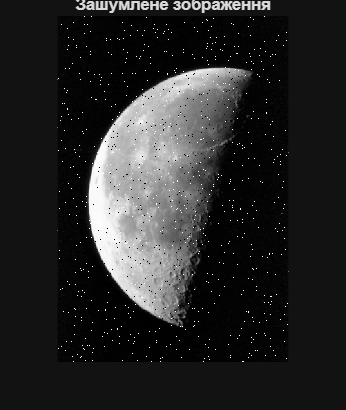

noisy_image = imnoise(image, 'salt & pepper', 0.02);
figure, imshow(noisy_image), title('Зашумлене зображення');

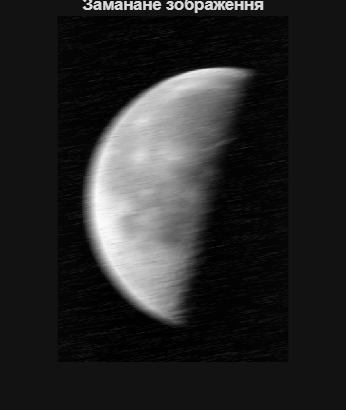


noisy_blurred = imfilter(noisy_image, PSF, 'conv', 'circular');
figure, imshow(noisy_blurred), title('Змазане зображення');

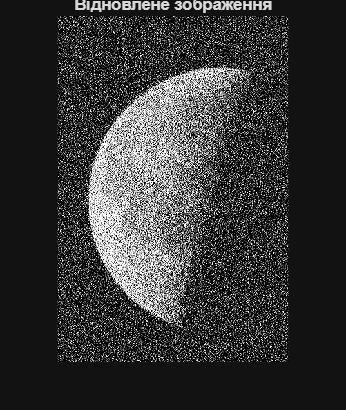


noisy_recovered = deconvwnr(noisy_blurred, PSF, 0);
imshow(noisy_recovered),title('Відновлене зображення');